## Fit bioluminescence and virus titers data with SCG model

Load experimental data

clear;clc;
data = importdata('data.txt');
data(:, 1) = data(:, 1) .* 24;  % from day to hour

Optimize using fminsearch

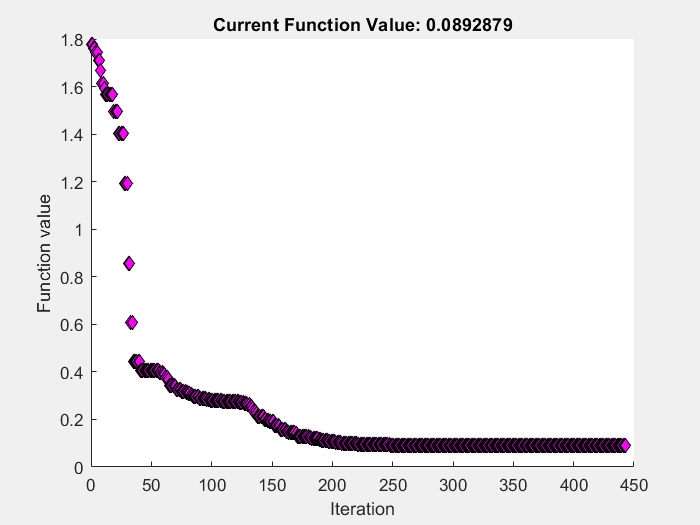

par_base = importdata('par_scg.txt');
par_base = par_base.data;

FitFcn = @(par_fit)Fit_err(data, par_fit);

options_fmin = optimset('PlotFcns',@optimplotfval);
[p, fminres] = fminsearch(FitFcn, par_base, options_fmin);

par_name = char('beta', 'k_I', 'd_I', 'p_V', 'c_V');
file = fopen('par_scg.txt', 'w');
for i = 1:length(p)
    fprintf(file, '%s, %.10f\n', par_name(i, :), p(i));
end
fclose(file);